# MATLAB做增强现实AR

同济子豪兄 https://space.bilibili.com/1900783

2021-08-04

## 载入A和C图像，初始化摄像头

clear global
% 初始化摄像头
global camera
camera = webcam('FaceTime高清摄像头（内建）');
% 等待一小段时间
pause(0.5);
% 先拍一张，但摄像头刚打开拍摄画面会比较黑暗
B = snapshot(camera);
% 等待一小段时间
pause(0.5);
% 再拍一张，画面就正常了
B = snapshot(camera);

% 初始化点追踪器
global pointTracker
pointTracker = vision.PointTracker('MaxBidirectionalError',2);

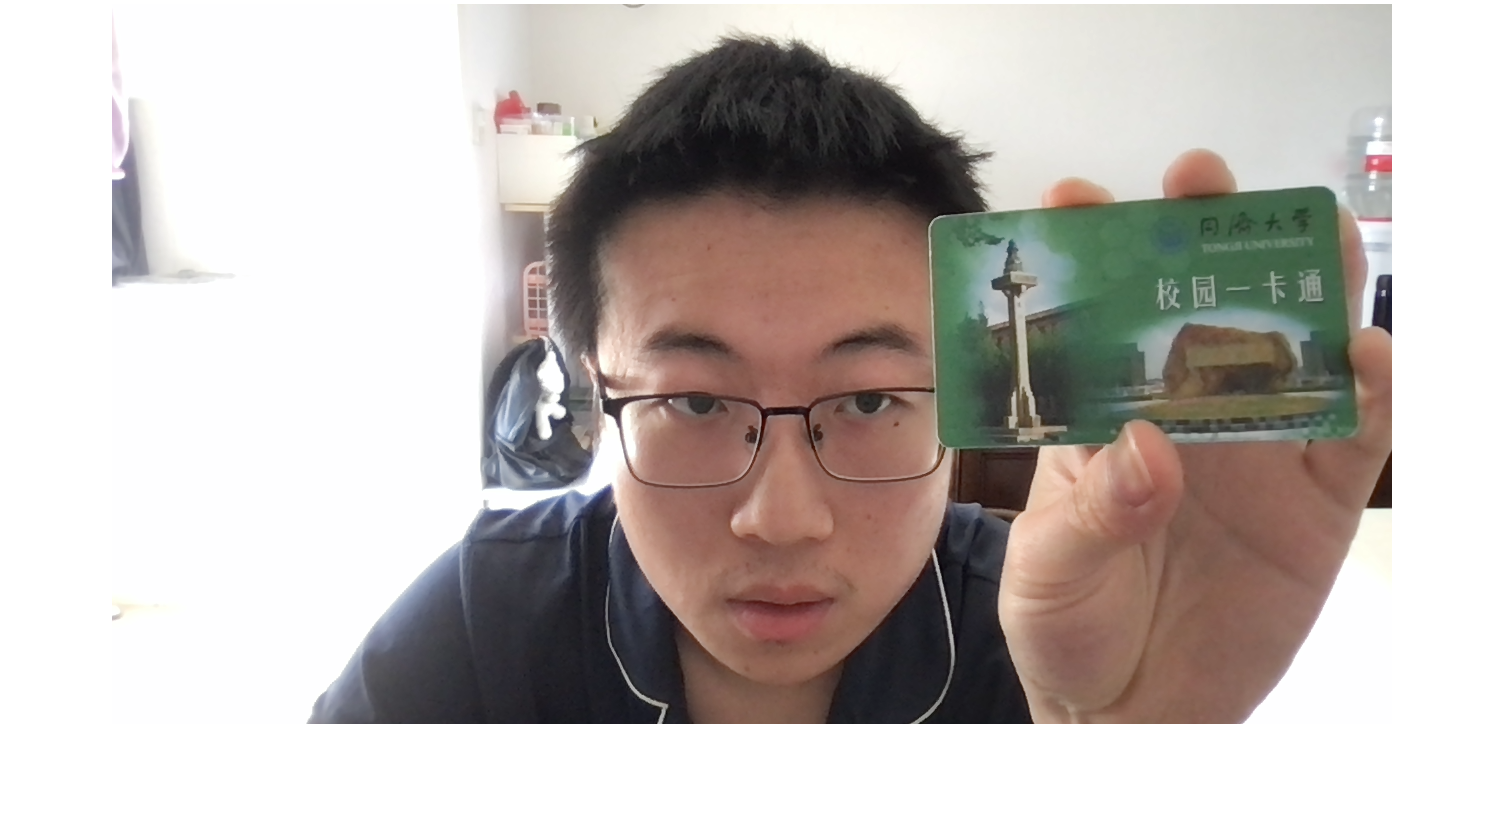

imshow(B);

global A
A = imread('A.png');
global C
C = imread('C.jpg');

% A图，转灰度图，提取特征
AGray = rgb2gray(A);
APts = detectSURFFeatures(AGray);
AFeatures = extractFeatures(AGray, APts);

global alphaBlender
alphaBlender = vision.AlphaBlender('Operation','Binary mask','MaskSource','Input port');

[matchedBPts, matchedAPts, CScaled, CTransformed, outputFrame, inlierBPts, referenceTransform, scaleTransform] = process_frame(A, AFeatures, APts, B, C);

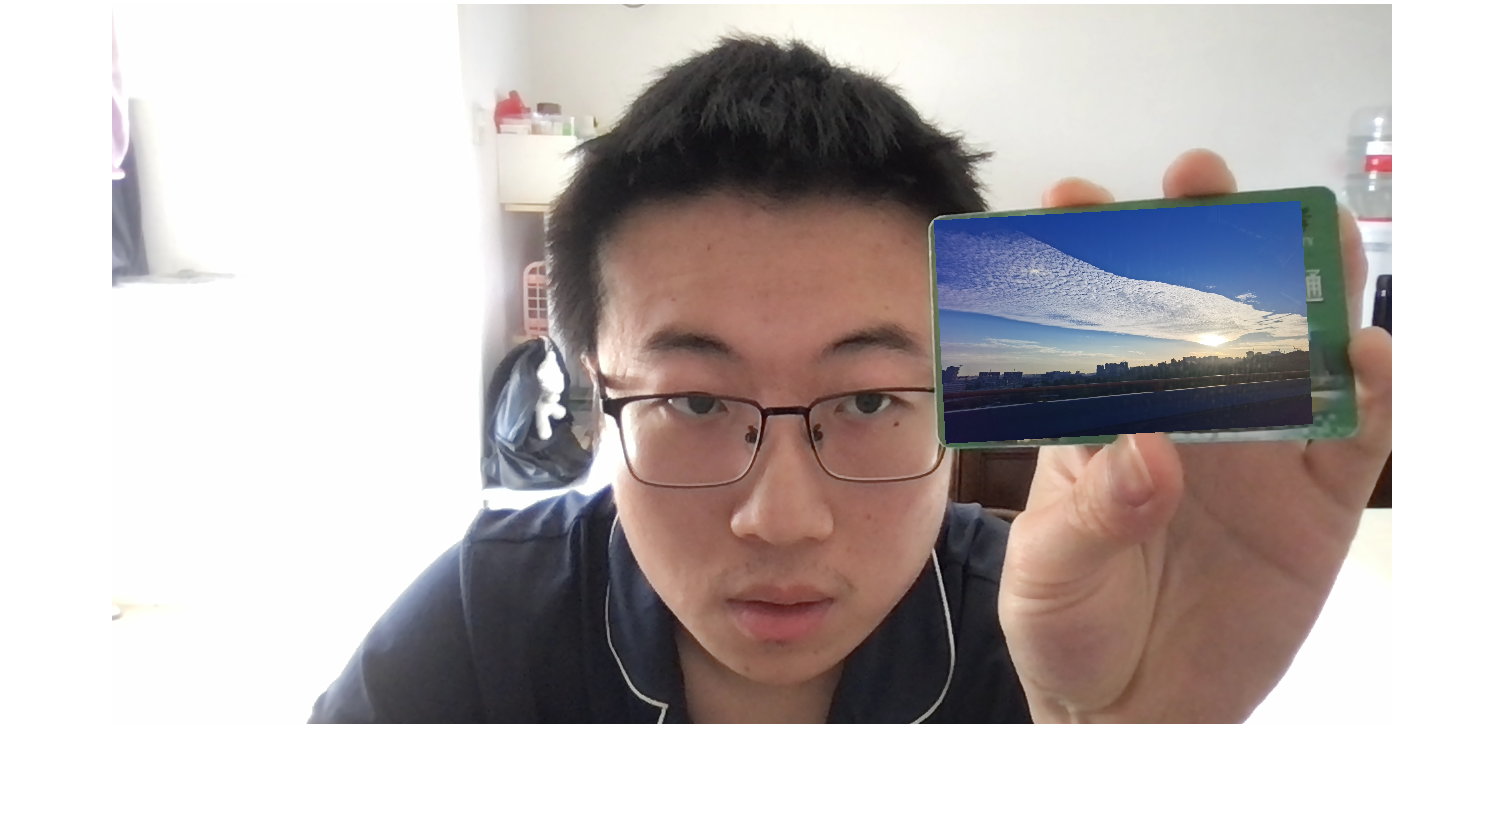

imshow(outputFrame)

## 追踪

[outputFrame] = process_tracking(B, inlierBPts, referenceTransform, scaleTransform, CScaled, CTransformed);

repFrame = 3840×2592×3 uint8 array
repFrame(:,:,1) =

  Columns 1 through 1,666

    30    31    32    31    30    30    30    30    30    28    29    30    29    26    28    32    33    29    29    32    31    30    31    32    33    30    30    31    31    29    30    32    30    29    28    29    31    31    31    30    30    31    30    30    31    31    29    30    32    33    31    30    34    34    29    31    32    31    31    32    32    31    31    32    32    32    32    32    33    33    32    32    31    31    32    32    32    32    32    32    31    31    31    30    31    32    33    33    33    34    34    32    32    34    35    35    34    34    34    33    33    34    33    32    33    33    33    32    33    33    34    35    33    35    40    43    47    51    51    50    49    50    49    48    50    48    47    47    47    49    49    47    46    48    48    45    44    46    47    48    47    46    46    47    46    46    48    50    49    49    50    51    50 

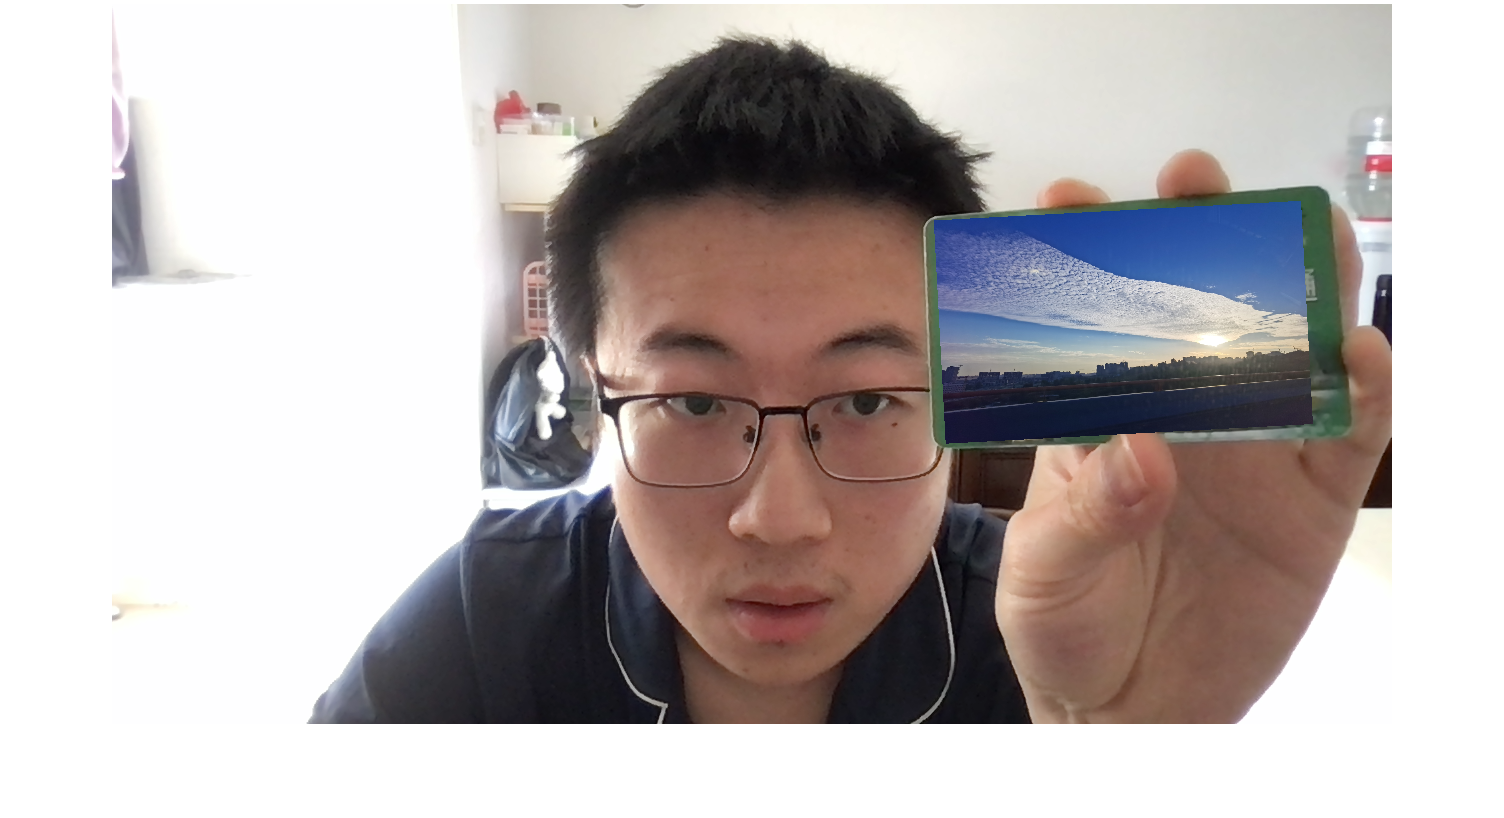

imshow(outputFrame)

## 定义函数findScaleTransform

function [scaleTransform ]=  findScaleTransform(refDims,repDims)
if (repDims(1)/repDims(2) > 1) && (refDims(2)/refDims(2) > 1) % 当两张图片长宽比相同时
    scaleTransform=affine2d([1/(repDims(1)/refDims(1)) 0 0 ; 0 1/(repDims(2)/refDims(2)) 0 ;0 0 1]);
else % 当两张图片长宽比不同时
    scaleTransform=affine2d([0 1/(repDims(2)/refDims(1))  0 ;  1/(repDims(1)/refDims(2)) 0 0 ;0 0 1]);
end
end

## 定义process_frame函数，输入ABC三张图像，输出中间结果和最终结果

function [matchedBPts, matchedAPts, CScaled, CTransformed, outputFrame, inlierBPts, referenceTransform, scaleTransform] = process_frame(A, AFeatures, APts, B, C)
global alphaBlender

% B图，转灰度图，提取特征
BGray = rgb2gray(B);
BPts = detectSURFFeatures(BGray);
BFeatures = extractFeatures(BGray, BPts);

% 两张图像的SURF特征匹配
idxPairs = matchFeatures(BFeatures, AFeatures);
% 分别取出匹配特征的第一列和第二列，可视化特征匹配结果
% 第一列对应B图的特征点位置
matchedBPts = BPts(idxPairs(:,1));
% 第二列对应A图的特征点位置
matchedAPts = APts(idxPairs(:,2));

% 计算A图和B图的几何变换关系
[referenceTransform, inlierAPts, inlierBPts] = estimateGeometricTransform(matchedAPts, matchedBPts, 'Similarity');

% C图
% 先将C图缩放至与A图相同大小
% 获取C图size
CDims = size(C(:,:,1));
% 获取A图size
ADims = size(A);

% find transformation that scales video frame to replacement iamge size
% preserving aspect ratio
scaleTransform = findScaleTransform(ADims, CDims);
outputView = imref2d(size(A));
CScaled = imwarp(C, scaleTransform, 'OutputView', outputView);

% 再将C图缩放至B图的校园卡对应区域
outputView = imref2d(size(B));
CTransformed = imwarp(CScaled, referenceTransform, 'OutputView', outputView);

% 将B图的校园卡区域替换成C图
% alphaBlender = vision.AlphaBlender('Operation','Binary mask','MaskSource','Input port');
% 选出CTransformed有图像的区域
mask = CTransformed(:,:,1) | CTransformed(:,:,2) | CTransformed(:,:,3) > 0;
outputFrame = step(alphaBlender, B, CTransformed, mask);

end

## 定义process_tracking函数，输入当前帧，拍摄下一帧，并返回追踪效果

function [outputFrame] = process_tracking(B, inlierBPts, referenceTransform, scaleTransform, CScaled, CTransformed)
global camera pointTracker A C alphaBlender

initialize(pointTracker, inlierBPts.Location, B);
% 展示用于追踪的点
trackingMarkers = insertMarker(B, inlierBPts.Location, 'x', 'Size', 10, 'Color', 'red');
% imshow(trackingMarkers);

% 存储上一帧摄像头拍摄到的画面
prevCameraFrame = B;
% 摄像头拍摄下一帧画面
B = snapshot(camera);

% 在下一帧画面中找到追踪点
[trackedPoints, isValid] = step(pointTracker, B);

% 前后两帧画面的高置信度对应追踪点 个数
% disp(nnz(isValid))

% 只选取两帧画面中的高置信度追踪点
newValidLocations = trackedPoints(isValid,:);
oldValidLocations = inlierBPts.Location(isValid,:);

% 前后两帧画面的高置信度对应追踪点 个数 超过2时
if (nnz(isValid) >=2)
    [trackingTransform, oldInlierLocations, newInlierLocations] = ...
        estimateGeometricTransform(...
            oldValidLocations, newValidLocations, 'Similarity');
end

% 展示上下两帧画面的高置信度对应追踪点
% showMatchedFeatures(prevCameraFrame, B, oldInlierLocations, newInlierLocations, 'Montage');

% 重启下一帧的点追踪
setPoints(pointTracker, newValidLocations);

% accumulate geometric transformations from reference to current Frame
trackingTransform.T = referenceTransform.T * trackingTransform.T;

% rescale new replacement video frame
% repFrame = step(video);
repFrame = C
outputView = imref2d(size(A));
videoFrameScaled = imwarp(C, scaleTransform, 'OutputView',outputView);

% apply total geometric transformation to new replacement video frame
outputView = imref2d(size(B));
videoFrameTransformed = imwarp(CScaled, trackingTransform, 'OutputView', outputView);

% imshow(videoFrameTransformed)

% 选出CTransformed有图像的区域
mask = CTransformed(:,:,1) | CTransformed(:,:,2) | CTransformed(:,:,3) > 0;

outputFrame = step(alphaBlender, B, CTransformed, mask);

end